Load data file (struct 3D format) and get axes order

% FolderPath = ['C:\Users\' getenv('USERNAME') '\MATLAB Drive\vars'];
FolderPath = 'D:\MATLAB\MATLAB Drive\vars';
SampleName = 'IB3 5E14 H-annealed TL 100um 2';
SweepID = 'A';
FileName = [SampleName ' ' SweepID];
SetName = '3D_sweep_order';
RealPath = [FolderPath '\' SampleName '\' FileName];
%RealPath = '' % Or put the path yourself

LoadedFile = load(RealPath)

LoadedFile = struct with fields:
     full_struct_vec_sweep_order_frequency_amplitude_offset: [1×441 struct]
    select_data_3D_desired_order_offset_frequency_amplitude: [1×1 struct]
      select_data_3D_sweep_order_frequency_amplitude_offset: [1×1 struct]


fNames = fieldnames(LoadedFile);
DataStruct = LoadedFile.(fNames{contains(fNames, SetName)});
Order = DataStruct.order;
% StrBeforeOrder = 'order_'; % input the string just before the first parameter
% Order = MFIA_get_order_from_path(fNames{contains(fNames,SetName)}, StrBeforeOrder)
title = RealPath(sum(find(RealPath=='\', 1, 'last'))+1:end)

title = 'IB3 5E14 H-annealed TL 100um 2 A'


SavePlotPath = [FolderPath '\' SampleName '\' title];


Save data slice plots

SaveDataPlots = true;

Select data to plot (leave empty to plot all data in 3D struct) and define plot aliases (from IA parametric model)

plt_select_data = {};
plt_select_data(:,end+1) = {'param0'; 'Resistance [ohm]'};
plt_select_data(:,end+1) = {'param1'; 'Capacitance [F]'};

Select axis range - data outside range is discarded from here onward (applies to all subsequent fits)

ax_range = {};
ax_range(:,end+1) = {'frequency'; [0 inf]};
ax_range(:,end+1) = {'amplitude'; [0 inf]}; 
ax_range(:,end+1) = {'offset'; [-inf inf]};

Select value range - data outside range is replaced with NaN from here onward (applies to all subsequent fits)

val_range = {};
val_range(:,end+1) = {'param0'; [0 inf]};
val_range(:,end+1) = {'param1'; [0 inf]};

Define slice planes

slice_planes = {};
slice_planes(:,end+1) = {'frequency'; [1e2 1e3 1e4 1e5 5e5]};
slice_planes(:,end+1) = {'amplitude'; []}; 
slice_planes(:,end+1) = {'offset'; [0 -0.1 -0.2 -0.5 -1 -1.5]};

Add plot formatting commands:

all: plt_cmds(2,end+1) =  {'comand'}; '' for ' inside string.

target: plt_cmds(:,end+1) =  {'target' ; 'comand'};

plt_cmds = {};
% plt_cmds(2,end+1) = {'grid on'};
plt_cmds(2,end+1) = {'colorbar(''eastoutside'')'};
plt_cmds(2,end+1) = {'colormap(s,''turbo'')'};
plt_cmds(2,end+1) = {'colormap(s,interp1(colormap(s), 1:(length(colormap(s))/998):length(colormap(s))))'};
% plt_cmds(:,end+1) = {'param0'; 'colormap(s,[compress_array_exp(colormap(s),10,10, ''Reverse'', true, ''Interp'', true)])'};
% plt_cmds(2,end+1) = {'colormap(s,[0 0 0; colormap(s)])'};
% plt_cmds(2,end+1) = {'colormap([colormap; 1 1 1])'};
plt_cmds(:,end+1) = {'param0'; 'caxis([0 1e7])'};
plt_cmds(:,end+1) = {'param1'; 'caxis([0 inf])'};

plt_log_freq = true; % true for log plot frequency
if plt_log_freq
    Order{contains(Order, 'frequency')} = 'log_frequency';
    ax_range(:,contains(ax_range(1,:), 'frequency')) = {'log_frequency'; log10(ax_range{2,contains(ax_range(1,:), 'frequency')})};
    slice_planes(:,contains(slice_planes(1,:), 'frequency')) = {'log_frequency'; log10(slice_planes{2,contains(slice_planes(1,:), 'frequency')})};
end

Plot slice planes of 3D data

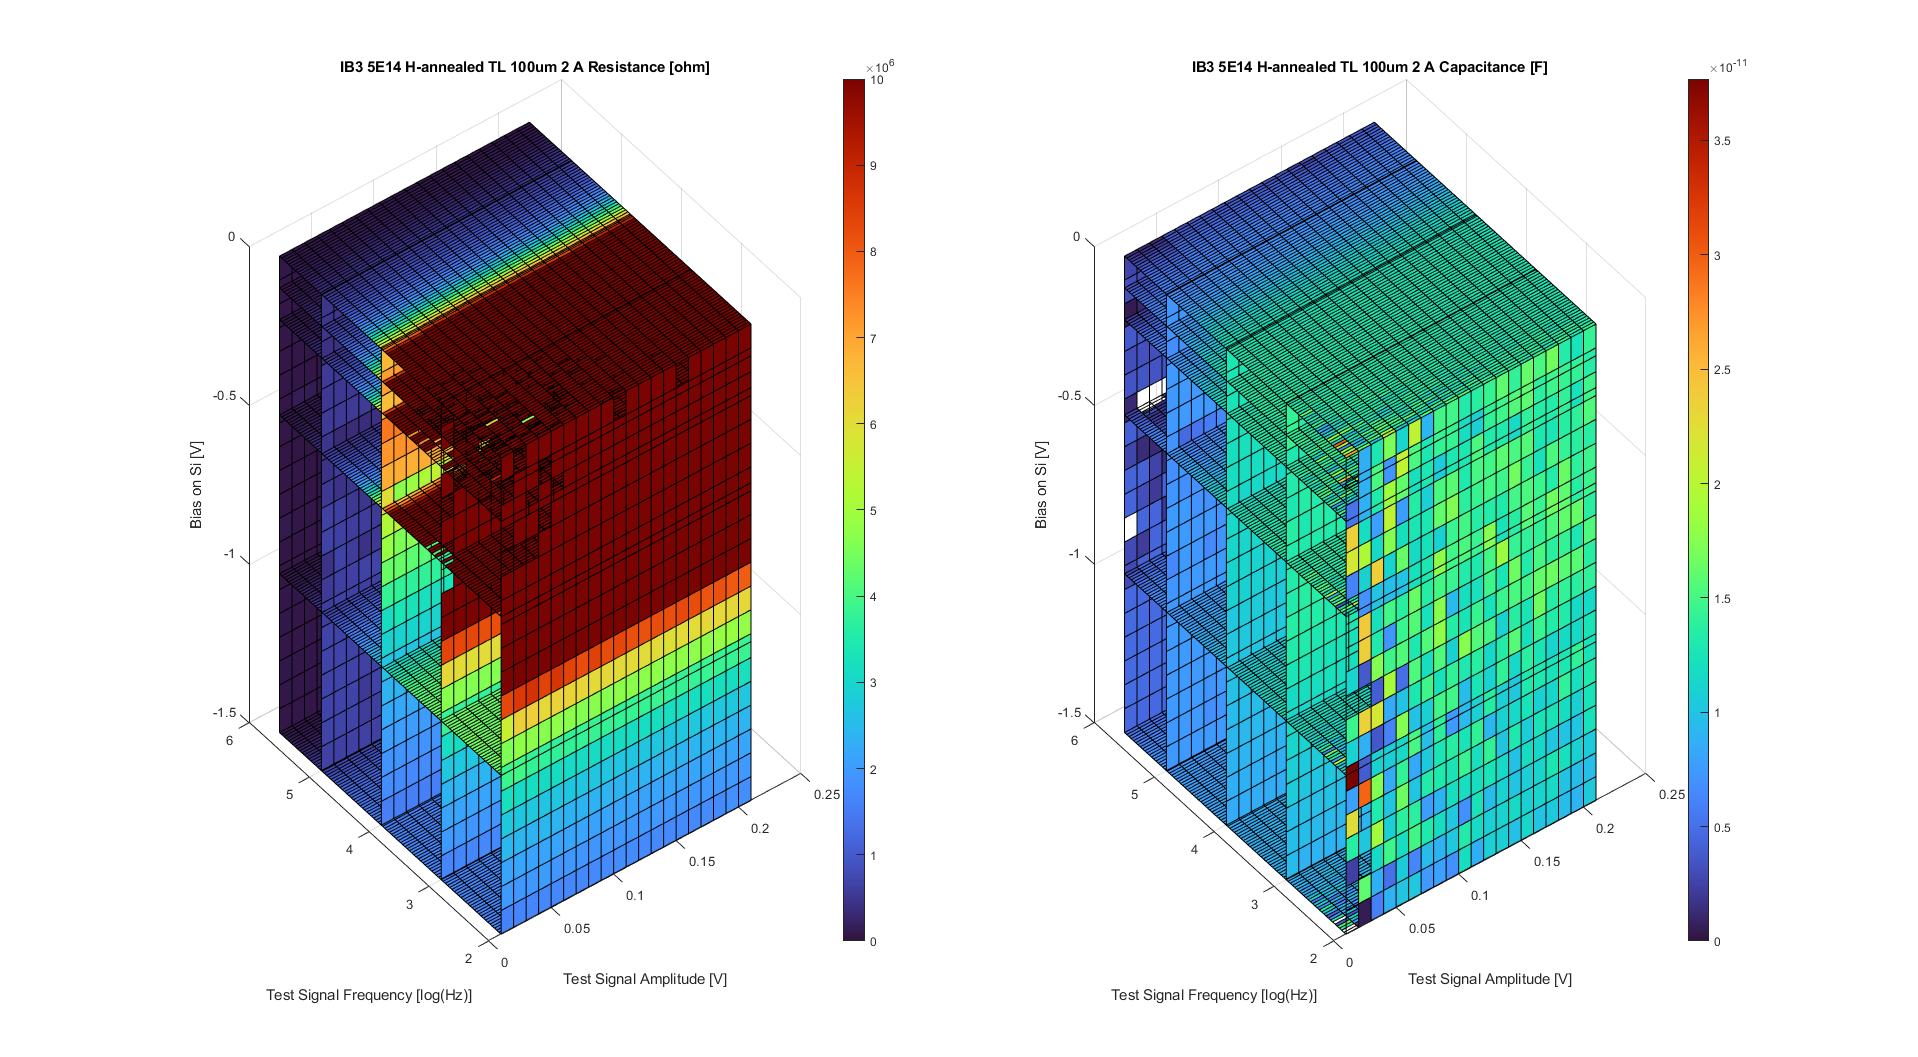

[PlotFig, SubPlots, DataCell, AxesCell] = process_plot_struct_data3D(DataStruct, Order, slice_planes, 'title', title, 'ax_range', ax_range, 'val_range', val_range, 'plt_select_data', plt_select_data, 'plt_cmds', plt_cmds);

if SaveDataPlots
    StartTime = datestr(now, 'yyyy-MM-dd HH-mm');
    mkdir(SavePlotPath);
    saveas(PlotFig, [SavePlotPath '\' FileName '_slice_plot ' StartTime '.fig']);
    saveas(PlotFig, [SavePlotPath '\' FileName '_slice_plot ' StartTime '.bmp']);
end

**Fit data along a certain dimension**

**C-V fit**

Plot and save options

Save_CV_plot = true;

CV_plot_fit = [];
CV_plot_fit.func = @plot;
CV_plot_fit.visible = 0;
CV_plot_fit.savepath = SavePlotPath;
% CV_plot_fit = [];

CV_fit_select = {'capacitance'};
CV_fit_axis = 'offset';

CV_val_range = {};
CV_val_range(:,end+1) = {''; [0 inf]};
CV_val_range(:,end+1) = {''; [0 inf]};

Fit function and options

CV_offset_range = [-inf inf];
syms V N Vb n
limits_A = {'Vb',[0 0.5 1],'N',[1e16 2e18 5e18],'n',[1 3 10]};
IdealityFactor = 1;
es = 11.68;
A = (150^2 * pi)*1e-8;
CV_fit_func = @(x,y) C_schot_fit_A(x,y,CV_offset_range,A,es,N,Vb,IdealityFactor);

[CV_fig, CV_sbp, CV_struct_array, CV_data_cell, CV_axes_cell, CV_FitAppendPath, CV_FitName] = fit_cell_3D(DataCell, AxesCell, CV_fit_func, CV_fit_axis, 'plt_select_data',CV_fit_select, 'title',title, 'plot_fit',CV_plot_fit, 'val_range', CV_val_range);

if Save_CV_plot
    CV_save_path = [SavePlotPath '\' CV_FitAppendPath];
    mkdir(CV_save_path);
    save([CV_save_path '\CV fit out ' CV_FitName], 'CV_struct_array','CV_data_cell','CV_axes_cell')
    saveas(CV_fig, [CV_save_path '\CV fit ' CV_FitName '.fig']);
    saveas(CV_fig, [CV_save_path '\CV fit ' CV_FitName '.bmp']);
end

**DLCP fit**

Save_DLCP_plot = true;

DLCP_plot_fit = [];
DLCP_plot_fit.func = @plot;
DLCP_plot_fit.visible = 0;
DLCP_plot_fit.savepath = SavePlotPath;
% DLCP_plot_fit = [];

DLCP_fit_select = {'capacitance'};  
DLCP_fit_axis = 'amplitude'; 

DLCP_val_range = {};
DLCP_val_range(:,end+1) = {'N'; [-1e18 1e18]};

Fit function and options

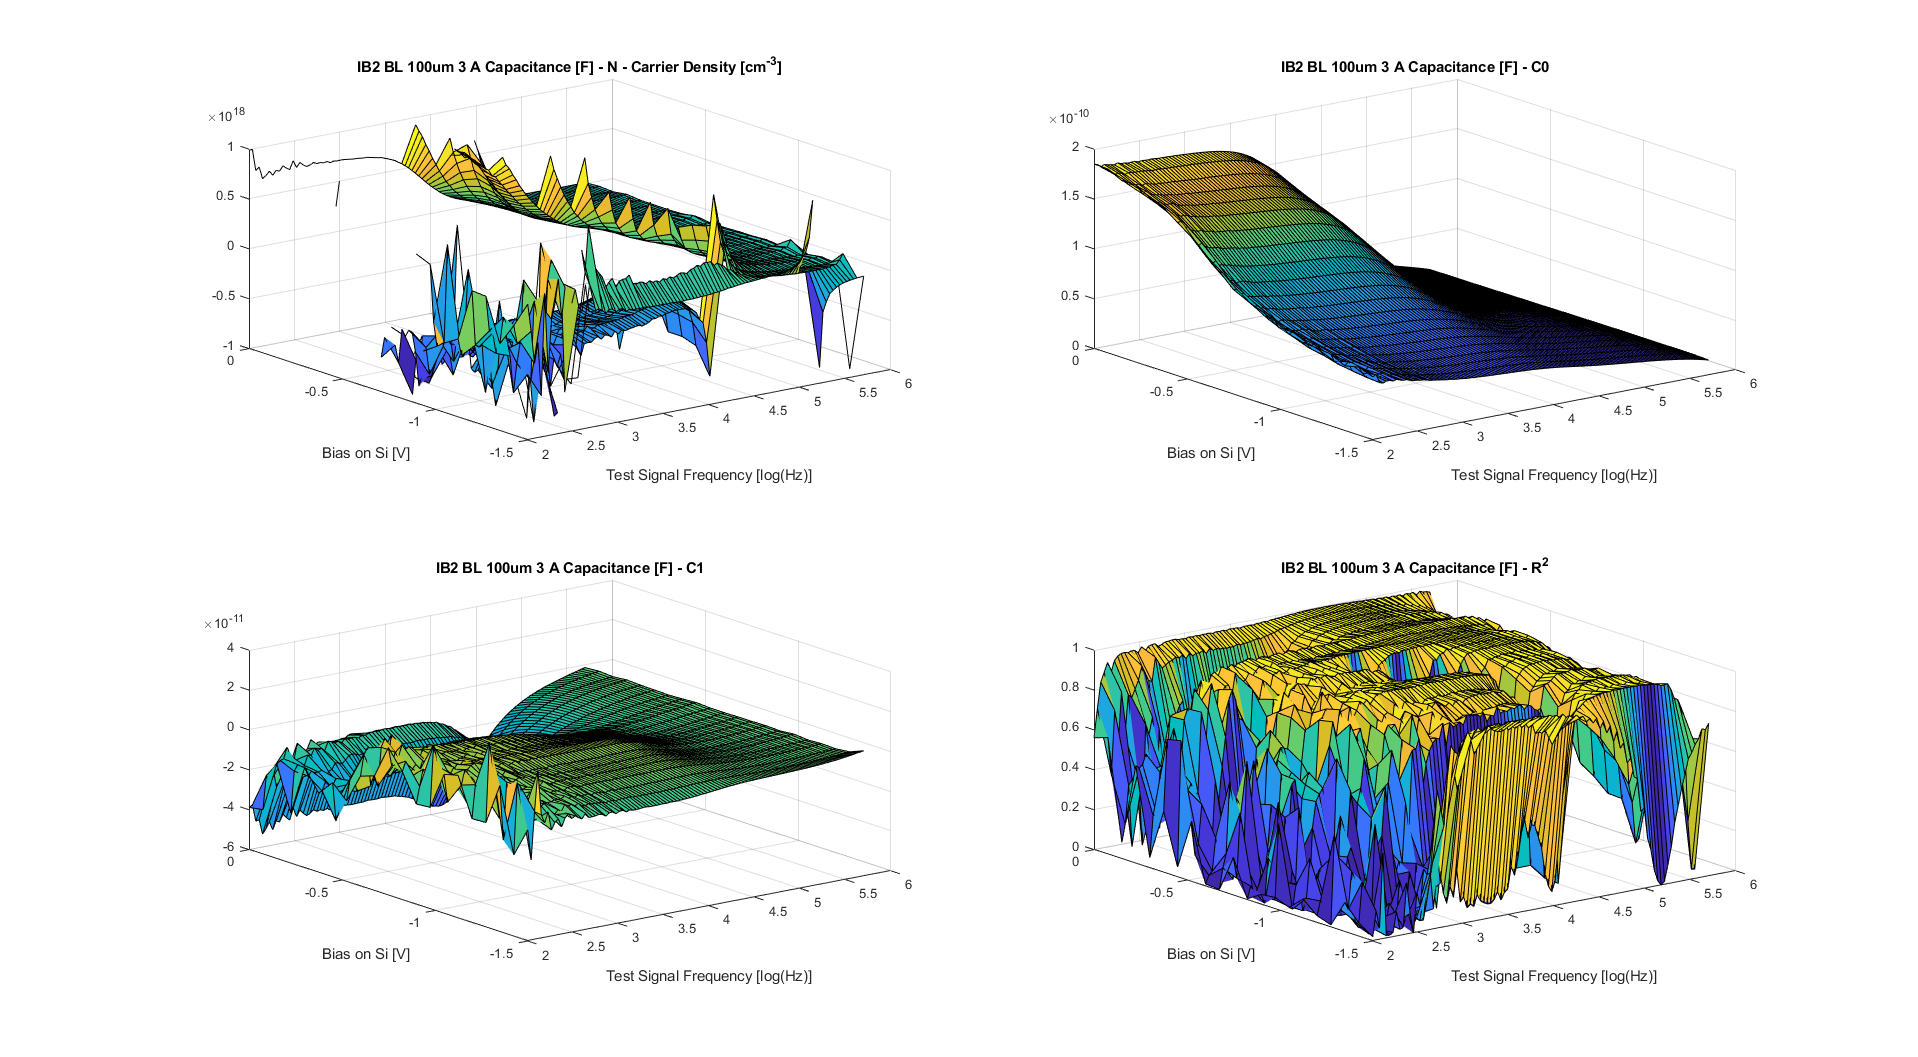

DLCP_amplitude_Range = [0.05 inf];
A = (150^2 * pi)*1e-8;
DLCP_fit_func = @(x,y) DLCP_fit(x,y, A, 'range',DLCP_amplitude_Range);

[DLCP_fig, DLCP_sbp, DLCP_struct_array, DLCP_data_cell, DLCP_axes_cell, DLCP_FitAppendPath, DLCP_FitName] = fit_cell_3D(DataCell, AxesCell, DLCP_fit_func, DLCP_fit_axis, 'plt_select_data',DLCP_fit_select, 'title',title, 'plot_fit',DLCP_plot_fit, 'val_range', DLCP_val_range);
if Save_DLCP_plot
    DLCP_save_path = [SavePlotPath '\' DLCP_FitAppendPath];
    mkdir(DLCP_save_path);
    save([DLCP_save_path '\DLCP fit_ ut ' DLCP_FitName], 'DLCP_struct_array','DLCP_data_cell','DLCP_axes_cell')
    saveas(DLCP_fig, [DLCP_save_path '\DLCP fit ' DLCP_FitName '.fig']);
    saveas(DLCP_fig, [DLCP_save_path '\DLCP fit ' DLCP_FitName '.bmp']);
end